%% part (b,c)

% system parameters

Mus = 30; % kg
Ms = 250; % kg
Kus = 150000; % N/m
Ks = 15000; % N/m
Bs = 1000; % N/m/s

% weights for optimization problem
q1 = 50000;
q3 = 5000;
gamma = 1;
r = 0;

% state space  description 

A =  [0 1 0 0; 
    -Kus / Mus, -Bs/Mus, Ks/Mus, Bs/Mus;
    0 -1 0 1;
    0 Bs/Ms -Ks/Ms -Bs/Ms];
B =  [0; Ms/Mus; 0; -1];
C =  [0 0 1 0];
D =  0;
E =  [-1 0 0 0]';
% open loop plant
Pyu = ss(A,B,C,D);
% open loop response of x4dot to disturbance
P_d = ss(A,E,A(4,:), 0);


A4 = A(4,:);
B4 = B(4);
Q = diag([q1, 0, q3, 0]) + A4' * gamma * A4;
R = B4'*gamma*B4;
S = A4' * gamma * B4;
K = lqr(A,B,Q,R,S)

K =     7.5407   -0.8734  -10.7107   -7.9666


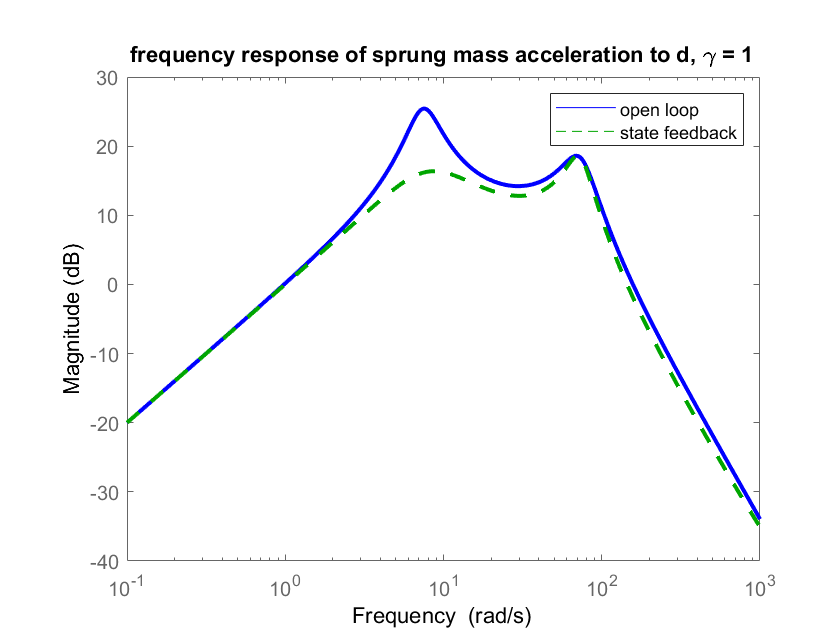



Asf =  A - B*K;
Bsf =  E;
Csf =  C;
Dsf =  D;

Tsf_d = ss(Asf,Bsf,Asf(4,:),0);

%% part (d)

figure(1)
clf

omega = logspace(-1,3,400);

bodemag(P_d,'b-',Tsf_d,'g--',omega)
legend('open loop','state feedback')
title(['frequency response of sprung mass acceleration to d, \gamma = ',num2str(gamma)])
set(findall(gcf,'type','line'),'linewidth',2)

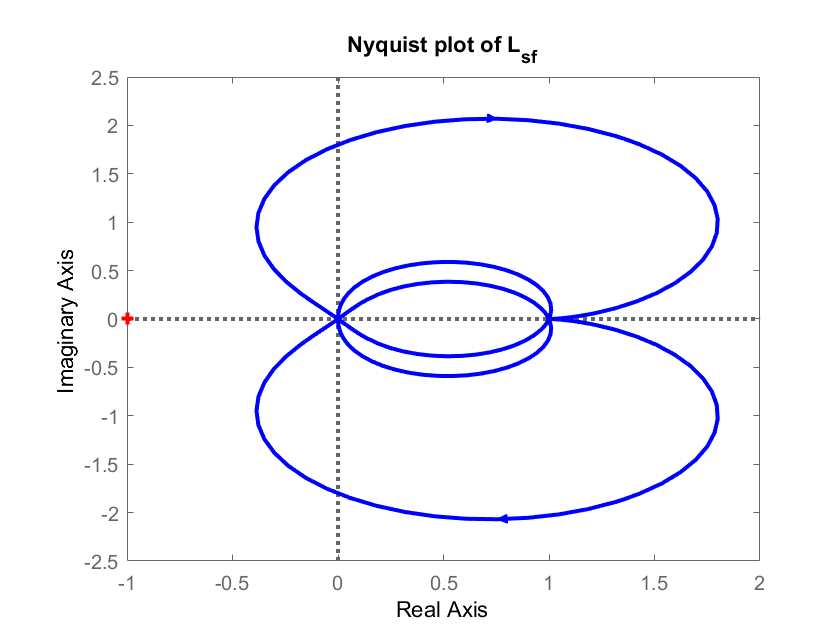

figure(2)
clf
s = tf('s');
 
Lsf =  minreal(A(4,:) / (s * eye(4) - A) * B);

nyquist(Lsf,'b-')
title('Nyquist plot of L_{sf}')
set(findall(gcf,'type','line'),'linewidth',2)

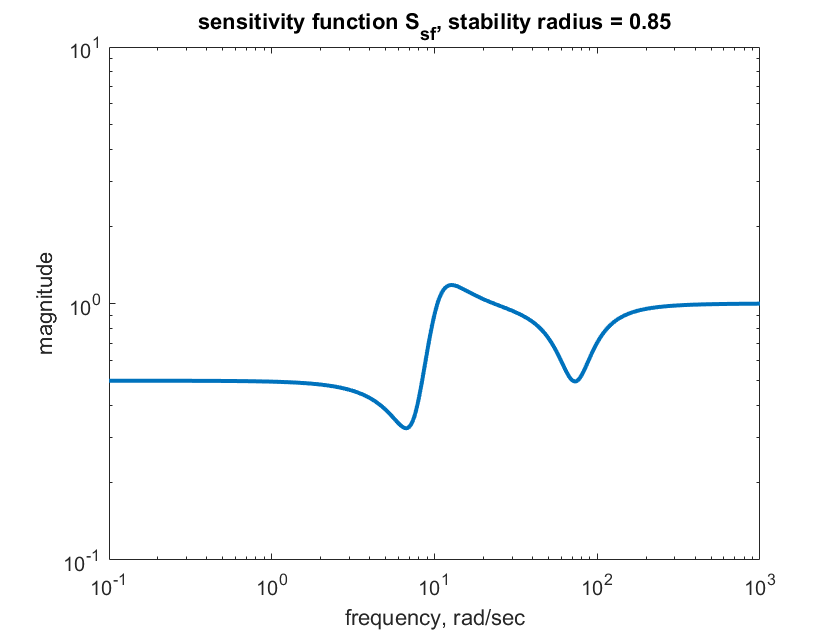


figure(3)
clf

Ssf =  1/ (1+Lsf);
[mag,phase] = bode(Ssf,omega);
mag = squeeze(mag);
stab_rad = 1/max(mag);
loglog(omega,mag)
title(['sensitivity function S_{sf}, stability radius = ',num2str(stab_rad,2)])
ylim([.1 10])
xlabel('frequency, rad/sec')
ylabel('magnitude')
set(findall(gcf,'type','line'),'linewidth',2)

The stability radius is less than 1 -> good?

%% part (f,g)
%%%%%%%%%%%%%%%%%%%%%%%%%%%  now design observer

% disturbance and measurement noise covariance matrices
V =  7e-4;  % (m/s)^2

V = 7.0000e-04

W =  1e-8;    % m^2

W = 1.0000e-08


 
L = lqe(A,E,C,V,W);